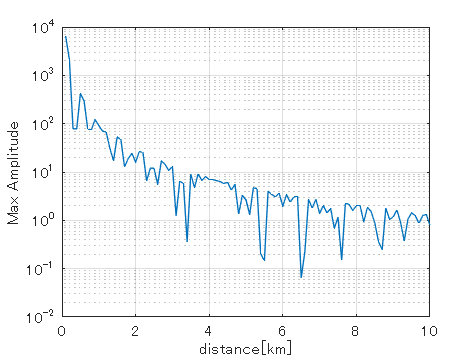

Dm = 5.56 * 10^(-2); %アンテナ間隔 ≒波長/2
Lm = 1000 * 1000; %距離 1000km
theta = pi * 3 / 6 ;
%dm = Dm * cos(theta);
freqHz = 2.675 * 10^9; %周波数
c = physconst('LightSpeed'); %光速
lambdam = c/freqHz; %波長
for h=1:1:100
    ht = h * 0.1; %0.1倍で0.1km刻みに
    tandelta = atan(ht*1*1000 / Lm); %θ求める
    theta = theta + tandelta;
    dm = Dm * cos(theta); %距離
    for i=1:100 %時間*10^11[s]
        amplititude1 = 1 * cos(2 * pi * freqHz * (i*10^(-11) - (Lm/c))); %1個目の波
        %amplititude2 = 1 * cos(2 * pi * freqHz * (i*10^(-11) - (Lm/c - (dm / c))));
        sum = 0 ;
        for j=1:9999 %アンテナ399個増やす
            amplititudefor=1 * cos(2 * pi * freqHz * (i*10^(-11) - (Lm/c) - (dm / c) * j)); %2個目以降の波
            sum = amplititudefor + sum; 
        end
        sum = sum + amplititude1; %波足し合わせ
        result(i) = sum;
    end
    max_result(h) = max(result); %波の最大
    %plot(result)
end
h=1:1:100;
semilogy(h*0.1,max_result) %対数グラフ
grid on
xlabel("distance[km]")
ylabel("Max Amplitude")

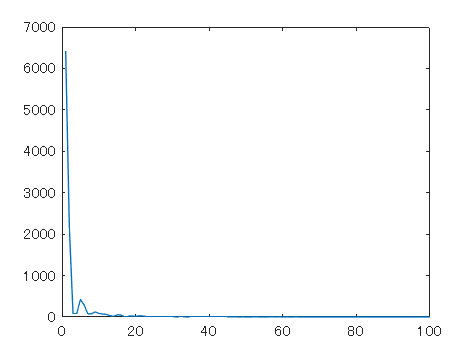


plot(max_result)